# x-MSI Part 1

- Code in Part 1 contains general steps as belows:

- Step 1：Import CDF Files and save as a peaklist

- Step 2：Delineate the Region Of Interest and Register Pixel Index

- Step 3：Generate the common peaks vector and construct a datacube

- Step 4：Reduce the datacube volume size by SNR and PDR criteria

- Step 5：Convert a datacube to a biomatrix

- Step 6：Spatial Segmentation for WBA /tumor

- Step 7：Biomatrix splitting and regional biomatrix recombination

- Step 8：Regional Metabolomic Feature Extraction

- Step 9：Measure the Metabolic Perturbation for global/high-order metabolomics

- Step 10：Construct Metabolic Perturbation Image for WBA/tumor

## Convert raw files to CDF files

- Use the File Converter in the Xcalibur software to convert raws file into cdf format

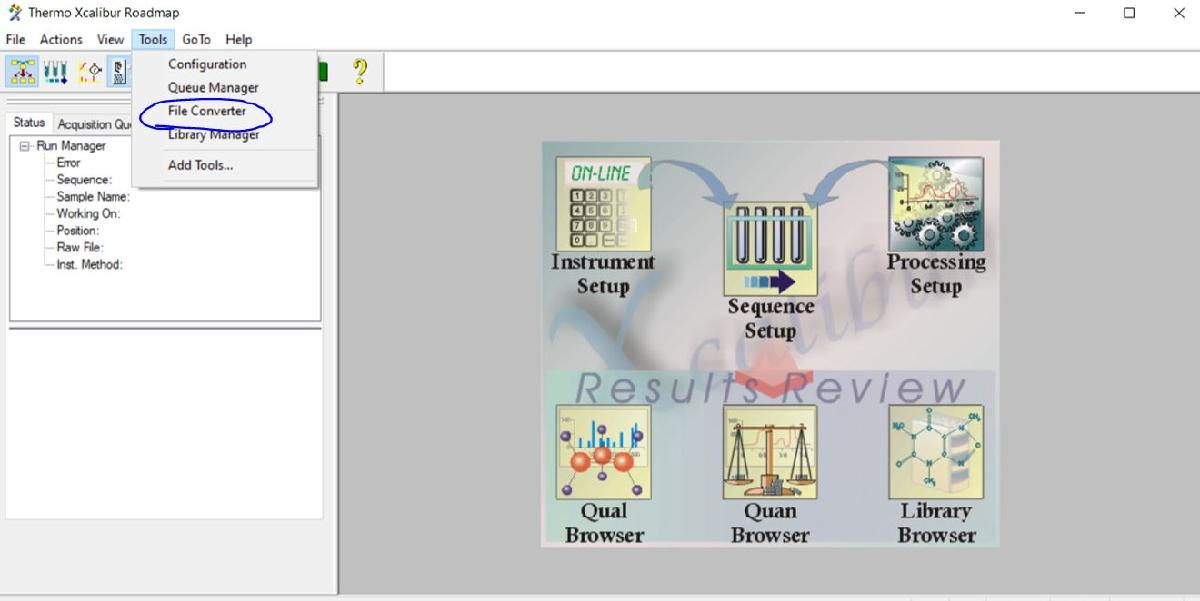

- specify the source data type, and folder, destination data type, and folder

- click "select all", "Add Job(s)", and "Convert".

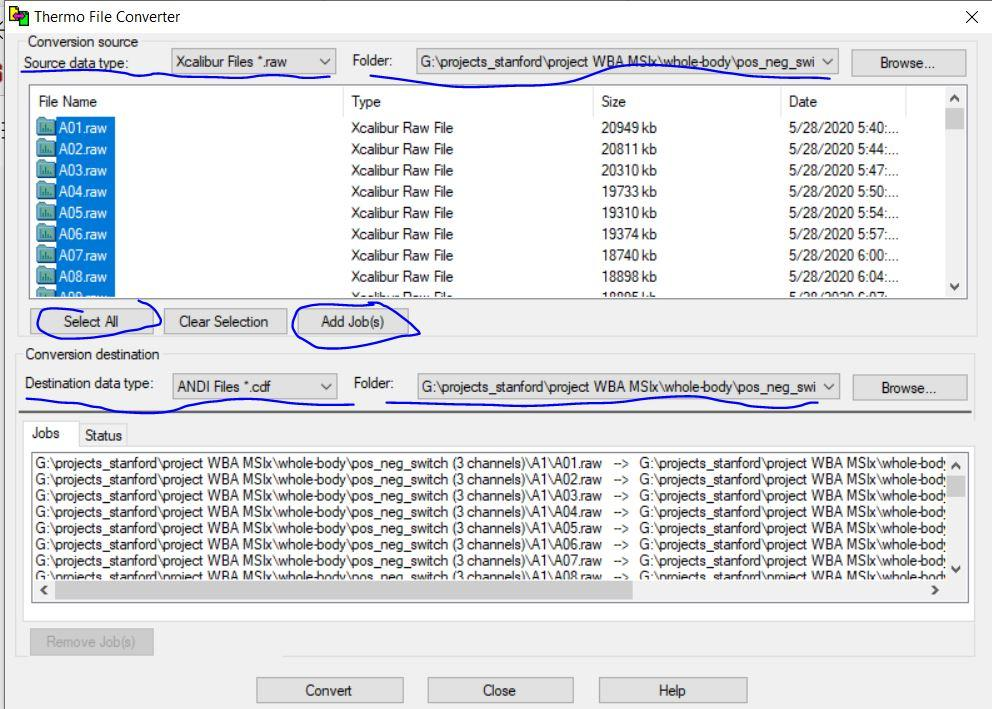

- create a separate folder to paste converted CDF files into it

- check the converted cdf files in the created new folder

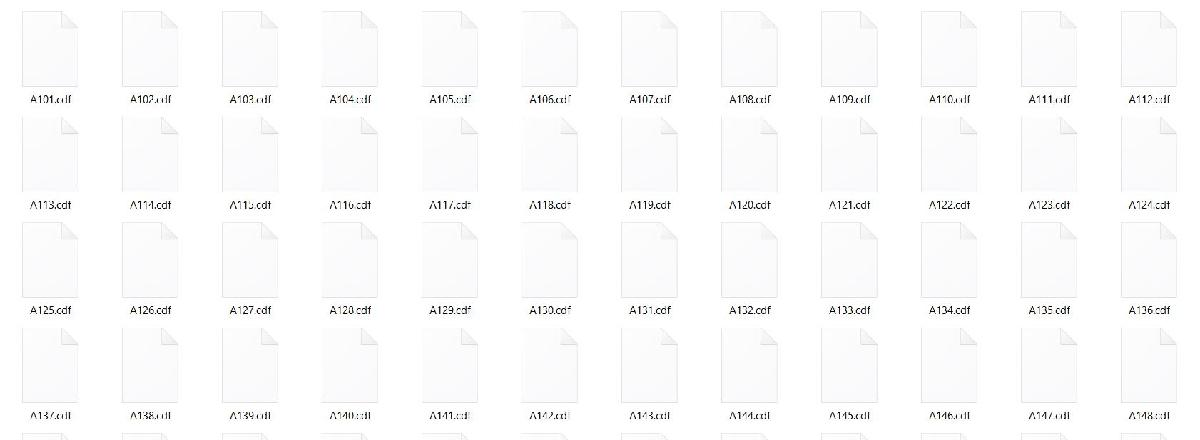

## Step 1 Import CDF Files and save as a peaklist

% reading series of No *.cdf files
% saved all of raw data into a cell named "peaklist"
prefix='A';
numOfFile=70
peaklist=batchcdfread(prefix,numOfFiles);
clear prefix numOfFiles
clc

- (Optional) Peaklist Splitting and Recombination

- If a peaklist is too large to save in the folder, split the whole peaklist into several parts for separate storage.

subpeaklist1=peaklist(1:32,:);
subpeaklist2=peaklist(33:end,:);

- Reload the subpeaklist into the workspace and combine them into one peaklist again when needed

load('subpeaklistA1.mat')
load('subpeaklistA2.mat')
peaklist=[subpeaklist1;subpeaklist2];
clear subpeaklist1 subpeaklist2
clc

- Convert the profile MS data into centroid MS data

% Only preserve peaks that have non-zero intensity values to save storage
% space
for i=1:length(peaklist)
    for j=1:length(peaklist{i})
        temp=peaklist{i,1}{j,1};
        peaklist{i,1}{j,1}=profile2centroid(temp);
    end
end
clear i j temp
clc

- Split the peaklist into three channel-specific peaklist

- Because an alternative scan were conducted on the whole-body animal (WBA) section, the whole peaklist will be splitted into three channels and separately saved.

for i=1:length(peaklist)
   peaklistneg{i,1}=peaklist{i,1}(1:3:end,1);
   peaklistpos{i,1}=peaklist{i,1}(2:3:end,1);
   peaklistdrug{i,1}=peaklist{i,1}(3:3:end,1);   
end
clear i
clc

## Step 2. Delineate the Region Of Interest and Register Pixel Index

- To remove the redundant pixels from the blank region

- Method 1: Automatic Selection 

- According to the sum of landmark (roi marker) ion intensities at each pixel and setted threshold value.

roimark_neg=[117.0193;118.0504;124.0064;132.0302;140.0117;...
    145.0619;151.0261;167.0207;171.0063;175.0240;191.0196;281.2468;...
    303.2317;371.1563;465.3057;515.2882;605.3062;663.3416;788.5441;885.5495];

% extract the negative landmark peak intensities of all pixels in the biomat
tolerance=0.005;
datacube_lm=batchmassimage(peaklist,roimark_neg,tolerance);
roimarksum=zeros(size(datacube_lm{1,2}))
for i=1:length(datacube_lm)
    roimarksum=roimarksum + datacube_lm{i,2};    
end
clear i tolerance roimark_neg
clc

% tune and set up the pixel selection threshold to get the clear boundary
% of biological sample region (ROI)
thres_roi=6E5;

% only preserve those pixels which the sum of marker ions intensities
% exceed the setted threshold value
roi=zeros(size(roimarksum,1)*size(roimarksum,2),1);
roi(roimarksum>thres_roi)=1;
roi=reshape(roi,[size(roimarksum,1),size(roimarksum,2)]);
imagesc(roi)

% (Optional) 
% delineate the ROI by positive landmark peaks
roimark_pos=[104.1071;146.1173;147.1128;162.1120;170.0332;...
    175.0000;175.1187;189.1595;203.2228;215.2223;296.0648;379.1314;...
    429.2393;465.2461;496.2412;756.5503;760.5805;772.5228;798.5383;806.5660];

% extract the positive landmark peak intensities of all pixels in the biomat
tolerance=0.005;
datacube_lm=batchmassimage(peaklistpos,roimark_pos,tolerance);
roimarksum=zeros(size(datacube_lm{1,2}))
for i=1:length(datacube_lm)
    roimarksum=roimarksum + datacube_lm{i,2};    
end
clear i tolerance roimark_pos
clc

% tune and set up the pixel selection threshold to get the clear boundary
% of biological sample region (ROI)
thres_roi=5E5;

% only preserve those pixels which the sum of marker ions intensities
% exceed the setted threshold value
roi=zeros(size(roimarksum,1)*size(roimarksum,2),1);
roi(roimarksum>thres_roi)=1;
roi=reshape(roi,[size(roimarksum,1),size(roimarksum,2)]);
imagesc(roi)

- (Optional) Method 2: Manual Selection (complementary with the automatic selection) 

- It is a quicker way to get the ROI. When the automatic selection still contain some obvious background pixels, the manual selection becomes the complementary choice.

- But it lacks the reproducibility and may also contain a few boundary background pixels.

% For negative image, arachidonic acid (m/z 303.2323) can be selected as the reference metabolite
mz=303.2323;
tolerance=0.005;
imagesc(massimage(peaklist,mz,tolerance));

% For positive image, choline (m/z 104.1070) can be selected as the reference metabolite
mz=104.1070;
tolerance=0.005;
imagesc(massimage(peaklist,mz,tolerance));
% Manual delineation of ROI
roi=roipoly;
% Draw the roi point-by point in the pop-up figure
% Right click---create mask

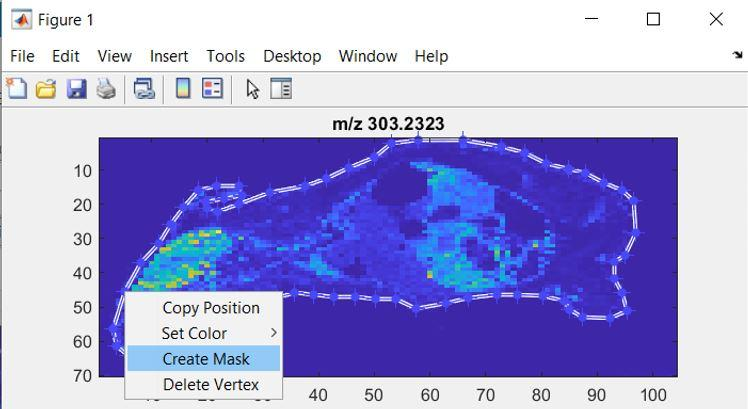

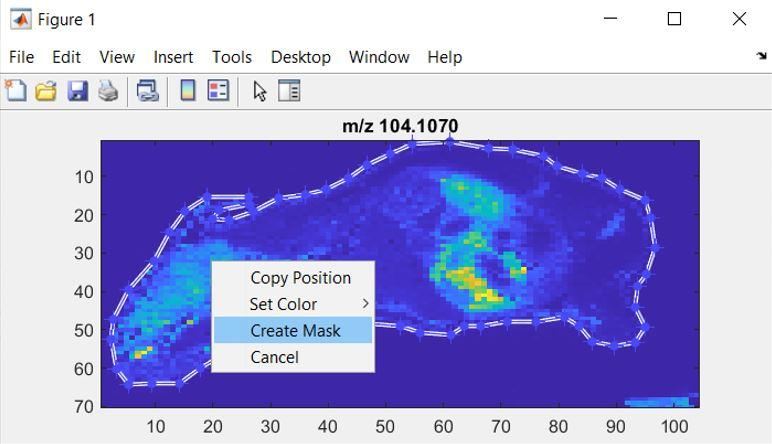

Figure. ROI region delineation by hand. The positive and negative image should share completely same ROI because of alternative scan data acquisition mode.

% generate the roi pixels' row and column index
[bio_r,bio_c]=find(roi==1);
biopix_indx=[bio_r,bio_c];
clear bio_r bio_c threshold landmarksum
clc

## Step 3：Generate the common peaks vector and construct a datacube

- Only applied to the untarget metabolomics. 

- For untargeted metabolomics, the common peaks' m/z values should be binned from each MS scan given certain mass tolerance.

% for generating the negative cmz
% note: it may take around 1 minutes in this section
tolerance=0.005;

cache=[];
for i=1:length(biopix_indx)
    cache=[cache;peaklistneg{biopix_indx(i,1),1}{biopix_indx(i,2)}(:,1)];
end

cache=sort(cache);
delta=[0;diff(cache)];
indx=find(delta>tolerance);
for i=1:length(indx)+1
    if i==1
       cmz_neg(i,1)=mean(cache(1:indx(1)-1));
    elseif i==length(indx)+1
       cmz_neg(i,1)=mean(cache(indx(i-1):end));
    else
       cmz_neg(i,1)=mean(cache(indx(i-1):indx(i)-1));
    end
end
clear indx i cache delta 
clc

% for generating the positive cmz
% note: it may takes around 1 minutes in this section
cache=[];
for i=1:length(biopix_indx)
    cache=[cache;peaklistpos{biopix_indx(i,1),1}{biopix_indx(i,2)}(:,1)];
end

cache=sort(cache);
delta=[0;diff(cache)];
indx=find(delta>tolerance);
for i=1:length(indx)+1
    if i==1
       cmz_pos(i,1)=mean(cache(1:indx(1)-1));
    elseif i==length(indx)+1
       cmz_pos(i,1)=mean(cache(indx(i-1):end));
    else
       cmz_pos(i,1)=mean(cache(indx(i-1):indx(i)-1));
    end
end
clear indx i cache delta tolerance
clc

- For target metabomics, all of common peaks's m/z values have been stored in the pre-built dictionary and can be simply widthdrawed.

load("dictionary_neg.mat")
cmz_neg=cell2mat(dictionary_neg(2:end,2));

load("dictionary_pos.mat")
cmz_pos=cell2mat(dictionary_pos(2:end,2));

## Step 4：Reduce the datacube volume size by SNR and PDR criteria

% for WBA, sum up the total number of positive detection in all groups
% only preserve the sum of PDR large than 4 (groups).
% extract the bioinformative peak images to form the biodatacube
addpath 'D:\matlab\data\MSI(x)\part1\commonly used data'
load('snr_stata_pos.mat')
load('snr_stata_neg.mat')
biopk_indx_pos=find(cell2mat(snr_stata_pos(2:end,9))>=4);
biopk_indx_neg=find(cell2mat(snr_stata_neg(2:end,9))>=4);

clear biopk_indx_pos biopk_indx_neg

% take a intuitive overview of the peak distribution
subplot(1,2,1)
histogram(cell2mat(snr_stata_pos(2:end,9)))
xlabel('number of positive detection samples')
ylabel('number of peaks')
title('Positive Channel')

subplot(1,2,2)
histogram(cell2mat(snr_stata_neg(2:end,9)))
xlabel('number of positive detection samples')
ylabel('number of peaks')
title('Negative Channel')

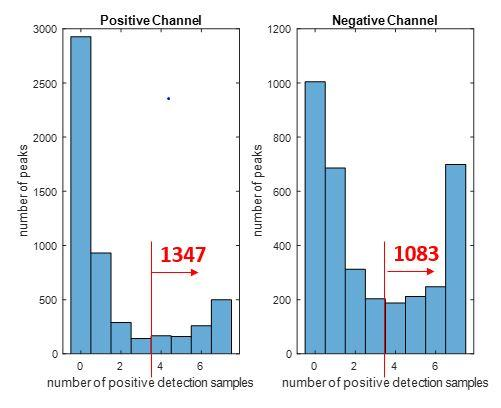

## Step 6：Spatial Segmentation for WBA/tumor

% TIC normalization
tic=sum(biomat,2);
biomatNorm=1E7*biomat./repmat(tic,1,size(biomat,2));

% natural log transform
biomatNormlog=log(biomatNorm+1);

% use t-stochastic neighbouring embedding to compress the high-dimension
% data into a 3D feature space
lv=tsne(biomatNormlog,...
'algorithm','exact',...
'distance','euclidean',...
'NumPCAComponents',30,...
'Standardize',1,...
'perplexity',30,...
'exaggeration',10,...
'verbose',1,...
'NumDimensions',3);

% use k means clustering to give a raw segmentation result
numOfLabel=15
label_rough=kmeans(lv(:,1:3),numOfLabel);
figure(1)
scatter3(lv(:,1),lv(:,2),lv(:,3),10,label_rough);
% verification by remapping into the 2D space
figure(2)
imagesc(indximg(label_rough,biopix_indx(:,1),biopix_indx(:,2)));
colormap(jet(13));

- Note: At the stage of spatial segmentation model development, biological pixels are first roughly classified (saved as "label_rough") by an unsupervised clustering method. Afterward, labelled pixels are carefully double-checked (saved as "label_precise") to removed those apparently wrong or ambiguous ones under guidance of optical image. Only those pixels with confident region assignment are included into the final training dataset, which is composed by labled pixels from whole-body animal sections' image in the healthy control group. 

- % extract the regional biomatrix and save the intensity matrix and corresponding index matrix into the bioarray and indxarray, respectively.

- % for tumor: C(cancer); T(taxol); R(ptx-R); L(ptx-sa,low); M(ptx-sa,medium); H(ptx-sa,high)

- Row Label for tumor microcompartment: 1. stroma (Muscle & Collagen) 2. parenchyma 3. Necrosis

% recall the pretrained model to predict labels of pixels from another
% unseen WBA section image data, for example: matlog_B (WBA from the B group)
% the pretrained model is saved as "trainedModel_cosKNN.mat"
load('cosKNN.mat')
mat_test=matlog_;
label_precise=cosKNN.predictFcn(mat_test);
% check the spatial segmentation performance by reconstructing the label
% image
label_image=indximg(label_precise,biopix_indx(:,1),biopix_indx(:,2));
imagesc(label_image);

- (Optional) Machine Learning Model Development for Spatial Segmentation

- You can either develop a machine learning model for spatial segmentation or directly use the pre-trained model by authors.

- The in-built app "classification learner" is an user-friendly way to train a model. The whole process can be completed in a graphic user interface (GUI). More details about this instruction can be accessed from the MATLAB help document.

- 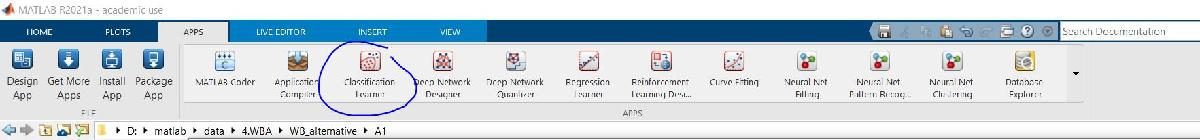

% suppose we already have confidently labelled pixels save in the variabe
% named label_precise
trainset_target=label_precise;
trainset_input=matlog;
% to predict regional labels of unseen new data using the pre-developed model
label_precise=quadSVM.predictFcn(testset_neg);

## Step 8：Regional Metabolomic Feature Extraction

% extract the spatial metabolomic feature from each region using t-SNE
% This step mat take around 10-15 minutes
numOfLabel=15;
tic
for i=1:numOfLabel
  cache=packer{i,1};
  % TIC norm
  tic=sum(cache,2);
  cacheNorm=1E7*cache./repmat(tic,1,size(cache,2));
  cacheNormLog=log(cacheNorm+1);
  % Feature Extraction by t-SNE
  featureArray{i,1}=tsne(cacheNormLog,'algorithm','exact','distance','euclidean',...
    'NumPCAComponents',100,'Standardize',1,'perplexity',30,'exaggeration',7,...
    'verbose',1,'NumDimensions',2);
end
clear i tic cache cacheNorm cacheNormLog
clc
toc